close all
clc

syms b d_1 d_2 d_3 d_4 d_5 d_6 d_7 d_8 m
syms beta eta tau lambda k p
syms u_v u_1 u_2 u_p
syms sigma_1 sigma_2 sigma_6
syms gamma_1 gamma_2 gamma_3
syms rho_1 rho_2
syms lambda_1 lambda_2 lambda_3 lambda_4 lambda_5 lambda_6 lambda_7 lambda_8

syms S E I_a Q I_1 I_2 R V
syms alpha_1 delta_1 delta_2 delta_3 delta_4 
syms theta_1 theta_2 theta_3 theta_4 zeta alpha_2

% step=1;

% t=1:step:10;

% S = zeros(1, length(t));
% E = zeros(1, length(t));
% I_a = zeros(1, length(t));
% Q = zeros(1, length(t));
% I_1 = zeros(1, length(t));
% I_2 = zeros(1, length(t));
% R = zeros(1, length(t));
% V = zeros(1, length(t));
% T = zeros(1, length(t));

StateVar = [S E I_a Q I_1 I_2 R V];
%S(i+1) = S(i)+step*(b-(+d_1+beta*I_a(i)*(1-u_p)+u_v)*S(i)+eta*R(i));
%E(i+1) = E(i)+step*(beta*I_a(i)*(1-u_p)*S(i)-(d_2+k)*E(i));
%I_a(i+1) = I_a(i)+step*(-(d_3+lambd_a*tau+gamma_1)*I_a(i)+k*E(i));
%Q(i+1) = Q(i)+step*(-(d_4+gamma_2+sigma_1)*Q(i)+p*lambda*tau*I_a(i));
%I_1(i+1) = I_1(i)+step*(-(d_5+gamma_3+rho_1*u_1+sigma_2*(1-u_1))*I_1(i)+sigma_1*Q(i)+(1-p)*lambda*tau*I_a(i));
%I_2(i+1) = I_2(i)+step*(-(d_6+m+rho_2*u_2)*I_2(i)+sigma_2*(1-u_1)*I_1(i));
%R(i+1) = R(i)+step*(-(eta+d_7)*R(i)+gamma_1*I_a(i)+gamma_2*Q(i)+(gamma_3+rho_1*u_1)*I_1(i)+rho_2*u_2*I_2(i));
%V(i+1) = V(i)+step*(-d_8*V(i)+u_v*S(i));
%System=[S(i+1) E(i+1) I_a(i+1),Q(i+1),I_1(i+1),I_2(i+1),R(i+1),V(i+1)];

System = [(b - (+d_1 + beta * I_a * (1 - u_p) + u_v) * S + eta * R )
    (beta * I_a * (1 - u_p) * S - (d_2 + k) * E)
    (-(d_3 + lambda * tau + gamma_1) * I_a + k * E)
    (-(d_4 + gamma_2 + sigma_1) * Q + p * lambda * tau * I_a)
    (-(d_5 + gamma_3 + rho_1 * u_1 + sigma_2 * (1 - u_1)) * I_1 + sigma_1 * Q + (1 - p) * lambda * tau * I_a)
    (-(d_6 + m + rho_2 * u_2) * I_2 + sigma_2 * (1 - u_1) * I_1)
    (-(eta + d_7) * R + gamma_1 * I_a + gamma_2 * Q + (gamma_3 + rho_1 * u_1) * I_1 + rho_2 * u_2 * I_2)
    (-d_8 * V + u_v * S)];
display(System);

$$System = \left(\begin{array}{c} b+R\,\eta -S\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)\\ -\text{E}\,\left(d_{2}+k\right)-I_{a}\,S\,\beta \,\left(u_{p}-1\right)\\ \text{E}\,k-I_{a}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)\\ I_{a}\,\lambda \,p\,\tau -Q\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)\\ Q\,\sigma_{1}-I_{1}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-I_{a}\,\lambda \,\tau \,\left(p-1\right)\\ -I_{2}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)-I_{1}\,\sigma_{2}\,\left(u_{1}-1\right)\\ I_{a}\,\gamma_{1}+Q\,\gamma_{2}+I_{1}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-R\,\left(d_{7}+\eta \right)+I_{2}\,\rho_{2}\,u_{2}\\ S\,u_{v}-V\,d_{8} \end{array}\right)$$


%StateVar = [S E I_a Q I_1 I_2 R V];%
%Matrix=sym('zero',[8 8]);
Matrix=[[-(d_1 + beta * I_a * (1 - u_p) + u_v ), 0, 0, 0, 0, 0, eta, 0],;
    [(beta * I_a * (1 - u_p)), - (d_2 + k), 0, 0, 0, 0, 0, 0],;
    [0, 0, (-(d_3 + lambda * tau + gamma_1)),0,0,0,0,0 ],;
    [0, 0, (p * lambda * tau), (-(d4 + gamma_2 + sigma_1)),0 ,0 ,0 ,0 ],;
    [0, 0, 0, sigma_1, -(d_5 + gamma_3 + rho_1 * u_1 + sigma_2 * (1 - u_1)),(rho_2 * u_2),0,0  ],;
    [0,0,0,0,sigma_2 * (1 - u_1) ,-(d_6 + m + rho_2 * u_2),0,0],;
    [0,0,gamma_1,gamma_2,(gamma_3 + rho_1 * u_1),rho_2 * u_2,-(eta + d_7),0],;
    [u_v,0,0,0,0,0,0,-d_8]];
display(Matrix);

$$Matrix = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{1}-u_{v}-d_{1} & 0 & 0 & 0 & 0 & 0 & \eta & 0\\ -\sigma_{1} & -d_{2}-k & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -d_{3}-\gamma_{1}-\lambda \,\tau & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \lambda \,p\,\tau & -\gamma_{2}-\sigma_{1}-\frac{8719666422421977}{295147905179352825856} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \sigma_{1} & \sigma_{2}\,\left(u_{1}-1\right)-\gamma_{3}-\rho_{1}\,u_{1}-d_{5} & \rho_{2}\,u_{2} & 0 & 0\\ 0 & 0 & 0 & 0 & -\sigma_{2}\,\left(u_{1}-1\right) & -d_{6}-m-\rho_{2}\,u_{2} & 0 & 0\\ 0 & 0 & \gamma_{1} & \gamma_{2} & \gamma_{3}+\rho_{1}\,u_{1} & \rho_{2}\,u_{2} & -d_{7}-\eta & 0\\ u_{v} & 0 & 0 & 0 & 0 & 0 & 0 & -d_{8} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{a}\,\beta \,\left(u_{p}-1\right) \end{array}$$



L =(-alpha_1*S + (1/2) * (delta_1 * u_p^2 + delta_2 * u_1^2 + delta_3 * u_2^2 + delta_4 * u_v^2));

L(end+1) =(theta_1 * I_1+theta_1 * I_2 + (1/2) * (delta_1 * u_p^2 + delta_2 * u_1^2 + delta_3 * u_2^2 + delta_4 * u_v^2));

L(end+1) =(-alpha_2 * S + theta_3 * I_1+theta_4 * I_2 + (1/2) * (delta_1 * u_p^2 + delta_2 * u_1^2 + delta_3 * u_2^2 + delta_4 * u_v^2));

L(end+1) =(zeta + (1/2) * (delta_1 * u_p^2 + delta_2 * u_1^2 + delta_3 * u_2^2 + delta_4 * u_v^2));

fileID = fopen('Report/data.txt','w');
for L = L
    lambda_0 = 1;
    
    length(System);
    
    Lambda = [lambda_1, lambda_2, lambda_3, lambda_4, lambda_5, lambda_6, lambda_7, lambda_8];
    
    
    disp(L)
    
    %array delle derivate
    Derivate_sys = [k, k, k, k, k, k, k];
    Derivate_lambda=[k, k, k, k, k, k, k];
    Derivate_control=[k,k,k,k];
    %array
    Control = [u_p,u_1,u_2,u_v];
    StateVar;
    Lambda;
    System;
    
    H = lambda_0 * L + Lambda * System;
    
    for elem = 1:length(System)
        display((System(elem)),char(StateVar(elem)));
    end
    disp(' ');
    %costate eq
    for elem = 1:length(System)
        Derivate_sys(elem) = diff(H, StateVar(elem));
        display((Derivate_sys(elem)),strcat('D_',char(StateVar(elem))));
    end
    disp(' ');
    for elem = 1:length(Lambda)
        Derivate_lambda(elem) = diff(H, Lambda(elem));
        %  display((Derivate_lambda(elem)),strcat('D_',char(Lambda(elem))));
    end
    
    for elem = 1:length(Control)
        Derivate_control(elem) = diff(H, Control(elem));
        display((Derivate_control(elem)),strcat('D_',char(Control(elem))));
    end
    
    
    
    soluzioni=solve(Derivate_control,Control);
    
    display(soluzioni.u_v)
    display(soluzioni.u_1)
    display(soluzioni.u_2)
    display(soluzioni.u_p)
    
    if true
        fprintf(fileID,'Cost Index %s\n',L);
        fprintf(fileID,'derivate_sys\n');
        fprintf(fileID,'%s\n',Derivate_sys);
        fprintf(fileID,'\n derivate_control\n');
        fprintf(fileID,'%s\n',Derivate_control);
        fprintf(fileID,'\n derivate_soluzionih \n');
        fprintf(fileID,'u_p=\n%s\n',soluzioni.u_p);
        fprintf(fileID,'u_1=\n%s\n',soluzioni.u_1);
        fprintf(fileID,'u_2=\n%s\n',soluzioni.u_2);
        fprintf(fileID,'u_v=\n%s\n',soluzioni.u_v);
        fprintf(fileID,'\n\n');
    end
end

$$\frac{\delta_{2}\,{u_{1}}^{2}}{2}+\frac{\delta_{3}\,{u_{2}}^{2}}{2}+\frac{\delta_{1}\,{u_{p}}^{2}}{2}+\frac{\delta_{4}\,{u_{v}}^{2}}{2}-S\,\alpha_{1}$$

$$S = b+R\,\eta -S\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)$$

$$E = -\text{E}\,\left(d_{2}+k\right)-I_{a}\,S\,\beta \,\left(u_{p}-1\right)$$

$$I\_a = \text{E}\,k-I_{a}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)$$

$$Q = I_{a}\,\lambda \,p\,\tau -Q\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$I\_1 = Q\,\sigma_{1}-I_{1}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-I_{a}\,\lambda \,\tau \,\left(p-1\right)$$

$$I\_2 = -I_{2}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)-I_{1}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$R = I_{a}\,\gamma_{1}+Q\,\gamma_{2}+I_{1}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-R\,\left(d_{7}+\eta \right)+I_{2}\,\rho_{2}\,u_{2}$$

$$V = S\,u_{v}-V\,d_{8}$$

$$D\_S = \lambda_{8}\,u_{v}-\alpha_{1}-\lambda_{1}\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)-I_{a}\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)$$

$$D\_E = k\,\lambda_{3}-\lambda_{2}\,\left(d_{2}+k\right)$$

$$D\_I\_a = \gamma_{1}\,\lambda_{7}-\lambda_{3}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)+\lambda \,\lambda_{4}\,p\,\tau +S\,\beta \,\lambda_{1}\,\left(u_{p}-1\right)-S\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)-\lambda \,\lambda_{5}\,\tau \,\left(p-1\right)$$

$$D\_Q = \gamma_{2}\,\lambda_{7}+\lambda_{5}\,\sigma_{1}-\lambda_{4}\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$D\_I\_1 = \lambda_{7}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-\lambda_{5}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-\lambda_{6}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$D\_I\_2 = \lambda_{7}\,\rho_{2}\,u_{2}-\lambda_{6}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)$$

$$D\_R = \eta \,\lambda_{1}-\lambda_{7}\,\left(d_{7}+\eta \right)$$

$$D\_V = -d_{8}\,\lambda_{8}$$

$$D\_u\_p = \delta_{1}\,u_{p}+I_{a}\,S\,\beta \,\lambda_{1}-I_{a}\,S\,\beta \,\lambda_{2}$$

$$D\_u\_1 = \delta_{2}\,u_{1}+I_{1}\,\lambda_{7}\,\rho_{1}-I_{1}\,\lambda_{6}\,\sigma_{2}-I_{1}\,\lambda_{5}\,\left(\rho_{1}-\sigma_{2}\right)$$

$$D\_u\_2 = \delta_{3}\,u_{2}-I_{2}\,\lambda_{6}\,\rho_{2}+I_{2}\,\lambda_{7}\,\rho_{2}$$

$$D\_u\_v = S\,\lambda_{8}-S\,\lambda_{1}+\delta_{4}\,u_{v}$$

$$ans = \frac{S\,\lambda_{1}-S\,\lambda_{8}}{\delta_{4}}$$

$$ans = \frac{I_{1}\,\lambda_{5}\,\rho_{1}-I_{1}\,\lambda_{7}\,\rho_{1}-I_{1}\,\lambda_{5}\,\sigma_{2}+I_{1}\,\lambda_{6}\,\sigma_{2}}{\delta_{2}}$$

$$ans = \frac{I_{2}\,\lambda_{6}\,\rho_{2}-I_{2}\,\lambda_{7}\,\rho_{2}}{\delta_{3}}$$

$$ans = -\frac{I_{a}\,S\,\beta \,\lambda_{1}-I_{a}\,S\,\beta \,\lambda_{2}}{\delta_{1}}$$

$$\frac{\delta_{2}\,{u_{1}}^{2}}{2}+\frac{\delta_{3}\,{u_{2}}^{2}}{2}+\frac{\delta_{1}\,{u_{p}}^{2}}{2}+\frac{\delta_{4}\,{u_{v}}^{2}}{2}+I_{1}\,\theta_{1}+I_{2}\,\theta_{1}$$

$$S = b+R\,\eta -S\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)$$

$$E = -\text{E}\,\left(d_{2}+k\right)-I_{a}\,S\,\beta \,\left(u_{p}-1\right)$$

$$I\_a = \text{E}\,k-I_{a}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)$$

$$Q = I_{a}\,\lambda \,p\,\tau -Q\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$I\_1 = Q\,\sigma_{1}-I_{1}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-I_{a}\,\lambda \,\tau \,\left(p-1\right)$$

$$I\_2 = -I_{2}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)-I_{1}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$R = I_{a}\,\gamma_{1}+Q\,\gamma_{2}+I_{1}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-R\,\left(d_{7}+\eta \right)+I_{2}\,\rho_{2}\,u_{2}$$

$$V = S\,u_{v}-V\,d_{8}$$

$$D\_S = \lambda_{8}\,u_{v}-\lambda_{1}\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)-I_{a}\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)$$

$$D\_E = k\,\lambda_{3}-\lambda_{2}\,\left(d_{2}+k\right)$$

$$D\_I\_a = \gamma_{1}\,\lambda_{7}-\lambda_{3}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)+\lambda \,\lambda_{4}\,p\,\tau +S\,\beta \,\lambda_{1}\,\left(u_{p}-1\right)-S\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)-\lambda \,\lambda_{5}\,\tau \,\left(p-1\right)$$

$$D\_Q = \gamma_{2}\,\lambda_{7}+\lambda_{5}\,\sigma_{1}-\lambda_{4}\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$D\_I\_1 = \theta_{1}+\lambda_{7}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-\lambda_{5}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-\lambda_{6}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$D\_I\_2 = \theta_{1}-\lambda_{6}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)+\lambda_{7}\,\rho_{2}\,u_{2}$$

$$D\_R = \eta \,\lambda_{1}-\lambda_{7}\,\left(d_{7}+\eta \right)$$

$$D\_V = -d_{8}\,\lambda_{8}$$

$$D\_u\_p = \delta_{1}\,u_{p}+I_{a}\,S\,\beta \,\lambda_{1}-I_{a}\,S\,\beta \,\lambda_{2}$$

$$D\_u\_1 = \delta_{2}\,u_{1}+I_{1}\,\lambda_{7}\,\rho_{1}-I_{1}\,\lambda_{6}\,\sigma_{2}-I_{1}\,\lambda_{5}\,\left(\rho_{1}-\sigma_{2}\right)$$

$$D\_u\_2 = \delta_{3}\,u_{2}-I_{2}\,\lambda_{6}\,\rho_{2}+I_{2}\,\lambda_{7}\,\rho_{2}$$

$$D\_u\_v = S\,\lambda_{8}-S\,\lambda_{1}+\delta_{4}\,u_{v}$$

$$ans = \frac{S\,\lambda_{1}-S\,\lambda_{8}}{\delta_{4}}$$

$$ans = \frac{I_{1}\,\lambda_{5}\,\rho_{1}-I_{1}\,\lambda_{7}\,\rho_{1}-I_{1}\,\lambda_{5}\,\sigma_{2}+I_{1}\,\lambda_{6}\,\sigma_{2}}{\delta_{2}}$$

$$ans = \frac{I_{2}\,\lambda_{6}\,\rho_{2}-I_{2}\,\lambda_{7}\,\rho_{2}}{\delta_{3}}$$

$$ans = -\frac{I_{a}\,S\,\beta \,\lambda_{1}-I_{a}\,S\,\beta \,\lambda_{2}}{\delta_{1}}$$

$$\frac{\delta_{2}\,{u_{1}}^{2}}{2}+\frac{\delta_{3}\,{u_{2}}^{2}}{2}+\frac{\delta_{1}\,{u_{p}}^{2}}{2}+\frac{\delta_{4}\,{u_{v}}^{2}}{2}-S\,\alpha_{2}+I_{1}\,\theta_{3}+I_{2}\,\theta_{4}$$

$$S = b+R\,\eta -S\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)$$

$$E = -\text{E}\,\left(d_{2}+k\right)-I_{a}\,S\,\beta \,\left(u_{p}-1\right)$$

$$I\_a = \text{E}\,k-I_{a}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)$$

$$Q = I_{a}\,\lambda \,p\,\tau -Q\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$I\_1 = Q\,\sigma_{1}-I_{1}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-I_{a}\,\lambda \,\tau \,\left(p-1\right)$$

$$I\_2 = -I_{2}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)-I_{1}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$R = I_{a}\,\gamma_{1}+Q\,\gamma_{2}+I_{1}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-R\,\left(d_{7}+\eta \right)+I_{2}\,\rho_{2}\,u_{2}$$

$$V = S\,u_{v}-V\,d_{8}$$

$$D\_S = \lambda_{8}\,u_{v}-\alpha_{2}-\lambda_{1}\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)-I_{a}\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)$$

$$D\_E = k\,\lambda_{3}-\lambda_{2}\,\left(d_{2}+k\right)$$

$$D\_I\_a = \gamma_{1}\,\lambda_{7}-\lambda_{3}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)+\lambda \,\lambda_{4}\,p\,\tau +S\,\beta \,\lambda_{1}\,\left(u_{p}-1\right)-S\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)-\lambda \,\lambda_{5}\,\tau \,\left(p-1\right)$$

$$D\_Q = \gamma_{2}\,\lambda_{7}+\lambda_{5}\,\sigma_{1}-\lambda_{4}\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$D\_I\_1 = \theta_{3}+\lambda_{7}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-\lambda_{5}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-\lambda_{6}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$D\_I\_2 = \theta_{4}-\lambda_{6}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)+\lambda_{7}\,\rho_{2}\,u_{2}$$

$$D\_R = \eta \,\lambda_{1}-\lambda_{7}\,\left(d_{7}+\eta \right)$$

$$D\_V = -d_{8}\,\lambda_{8}$$

$$D\_u\_p = \delta_{1}\,u_{p}+I_{a}\,S\,\beta \,\lambda_{1}-I_{a}\,S\,\beta \,\lambda_{2}$$

$$D\_u\_1 = \delta_{2}\,u_{1}+I_{1}\,\lambda_{7}\,\rho_{1}-I_{1}\,\lambda_{6}\,\sigma_{2}-I_{1}\,\lambda_{5}\,\left(\rho_{1}-\sigma_{2}\right)$$

$$D\_u\_2 = \delta_{3}\,u_{2}-I_{2}\,\lambda_{6}\,\rho_{2}+I_{2}\,\lambda_{7}\,\rho_{2}$$

$$D\_u\_v = S\,\lambda_{8}-S\,\lambda_{1}+\delta_{4}\,u_{v}$$

$$ans = \frac{S\,\lambda_{1}-S\,\lambda_{8}}{\delta_{4}}$$

$$ans = \frac{I_{1}\,\lambda_{5}\,\rho_{1}-I_{1}\,\lambda_{7}\,\rho_{1}-I_{1}\,\lambda_{5}\,\sigma_{2}+I_{1}\,\lambda_{6}\,\sigma_{2}}{\delta_{2}}$$

$$ans = \frac{I_{2}\,\lambda_{6}\,\rho_{2}-I_{2}\,\lambda_{7}\,\rho_{2}}{\delta_{3}}$$

$$ans = -\frac{I_{a}\,S\,\beta \,\lambda_{1}-I_{a}\,S\,\beta \,\lambda_{2}}{\delta_{1}}$$

$$\frac{\delta_{2}\,{u_{1}}^{2}}{2}+\frac{\delta_{3}\,{u_{2}}^{2}}{2}+\frac{\delta_{1}\,{u_{p}}^{2}}{2}+\frac{\delta_{4}\,{u_{v}}^{2}}{2}+\zeta$$

$$S = b+R\,\eta -S\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)$$

$$E = -\text{E}\,\left(d_{2}+k\right)-I_{a}\,S\,\beta \,\left(u_{p}-1\right)$$

$$I\_a = \text{E}\,k-I_{a}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)$$

$$Q = I_{a}\,\lambda \,p\,\tau -Q\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$I\_1 = Q\,\sigma_{1}-I_{1}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-I_{a}\,\lambda \,\tau \,\left(p-1\right)$$

$$I\_2 = -I_{2}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)-I_{1}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$R = I_{a}\,\gamma_{1}+Q\,\gamma_{2}+I_{1}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-R\,\left(d_{7}+\eta \right)+I_{2}\,\rho_{2}\,u_{2}$$

$$V = S\,u_{v}-V\,d_{8}$$

$$D\_S = \lambda_{8}\,u_{v}-\lambda_{1}\,\left(d_{1}+u_{v}-I_{a}\,\beta \,\left(u_{p}-1\right)\right)-I_{a}\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)$$

$$D\_E = k\,\lambda_{3}-\lambda_{2}\,\left(d_{2}+k\right)$$

$$D\_I\_a = \gamma_{1}\,\lambda_{7}-\lambda_{3}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)+\lambda \,\lambda_{4}\,p\,\tau +S\,\beta \,\lambda_{1}\,\left(u_{p}-1\right)-S\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)-\lambda \,\lambda_{5}\,\tau \,\left(p-1\right)$$

$$D\_Q = \gamma_{2}\,\lambda_{7}+\lambda_{5}\,\sigma_{1}-\lambda_{4}\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$D\_I\_1 = \lambda_{7}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-\lambda_{5}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-\lambda_{6}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$D\_I\_2 = \lambda_{7}\,\rho_{2}\,u_{2}-\lambda_{6}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)$$

$$D\_R = \eta \,\lambda_{1}-\lambda_{7}\,\left(d_{7}+\eta \right)$$

$$D\_V = -d_{8}\,\lambda_{8}$$

$$D\_u\_p = \delta_{1}\,u_{p}+I_{a}\,S\,\beta \,\lambda_{1}-I_{a}\,S\,\beta \,\lambda_{2}$$

$$D\_u\_1 = \delta_{2}\,u_{1}+I_{1}\,\lambda_{7}\,\rho_{1}-I_{1}\,\lambda_{6}\,\sigma_{2}-I_{1}\,\lambda_{5}\,\left(\rho_{1}-\sigma_{2}\right)$$

$$D\_u\_2 = \delta_{3}\,u_{2}-I_{2}\,\lambda_{6}\,\rho_{2}+I_{2}\,\lambda_{7}\,\rho_{2}$$

$$D\_u\_v = S\,\lambda_{8}-S\,\lambda_{1}+\delta_{4}\,u_{v}$$

$$ans = \frac{S\,\lambda_{1}-S\,\lambda_{8}}{\delta_{4}}$$

$$ans = \frac{I_{1}\,\lambda_{5}\,\rho_{1}-I_{1}\,\lambda_{7}\,\rho_{1}-I_{1}\,\lambda_{5}\,\sigma_{2}+I_{1}\,\lambda_{6}\,\sigma_{2}}{\delta_{2}}$$

$$ans = \frac{I_{2}\,\lambda_{6}\,\rho_{2}-I_{2}\,\lambda_{7}\,\rho_{2}}{\delta_{3}}$$

$$ans = -\frac{I_{a}\,S\,\beta \,\lambda_{1}-I_{a}\,S\,\beta \,\lambda_{2}}{\delta_{1}}$$




fprintf('Press Enter to plot some covid-19 data')

Press Enter to plot some covid-19 data

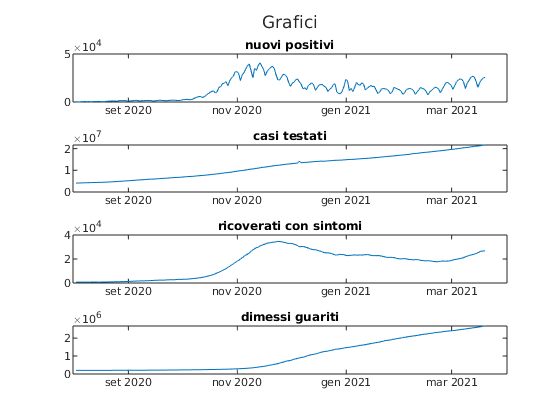

%pause


online_data=1;

if online_data==1
    fname='dati_covid.csv';
    websave(fname, 'https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-andamento-nazionale/dpc-covid19-ita-andamento-nazionale.csv');
    %opts= detectImportOptions(fname,"VariableNamesLine",1)
    TableReal=readtable(fname);
    %elseif online_data==2
    %Table=readtable('andamento_covid.csv');
end
if online_data==1
    %convert data from cell(string) to datetime
    
    TableReal(1:160,:)=[];
    TableReal.data=datetime(TableReal.data,"InputFormat","uuuu-MM-dd'T'HH:mm:ss","Format","uuuu-MM-dd");
    len=height(TableReal);
    initTime=TableReal.data(1);
    
    
    Figura=tiledlayout(4,1);
    title(Figura,'Grafici');
    nexttile;
    plot(TableReal.data,TableReal.nuovi_positivi);
    title('nuovi positivi');
    nexttile;
    plot(TableReal.data,TableReal.casi_testati);
    title('casi testati');
    nexttile;
    plot(TableReal.data,TableReal.ricoverati_con_sintomi);
    title('ricoverati con sintomi');
    nexttile;
    plot(TableReal.data,TableReal.dimessi_guariti);
    title('dimessi guariti');
    
    %    f= fit(datenum(Table.data),Table.casi_testati,'poly6');
    
end


% create the modelled evolution table

TableModelled=table('Size',[30 9],'VariableTypes',{'datetime','double','double','double','double','double','double','double','double'});

TableModelled.Properties.VariableNames=["date","S" ,"E" ,"I_a" ,"Q" ,"I_1" ,"I_2" ,"R", "V"];

TotalPopulation=60000000;
TotalPopulation=TotalPopulation-table2array(TableReal(1,"totale_positivi"));
TableModelled.date=datetime(TableModelled.date,"Format","uuuu-MM-dd");
TableModelled(1,:)={'2020-07-23',TotalPopulation,60000,30000,table2array(TableReal(1,"isolamento_domiciliare")),table2array(TableReal(1,"ricoverati_con_sintomi")),table2array(TableReal(1,"terapia_intensiva")),30000,0};


